addpath 'C:\Users\wsccs\Downloads\PRML\PattRecClasses\GetSpeechFeatures';
addpath 'C:\Users\wsccs\Downloads\PRML\PattRecClasses';
cd Actor_01;
fileName = ls;
feature = [];
featureLength = [];
[x0, fs] = audioread(fileName(3,:));
[mfccs1,spec1,f1,t0]=GetSpeechFeatures(x0(:,1),fs,0.03,13);
test = feature_normalized(mfccs1);

for i = 4:62
    [x, fs] = audioread(fileName(i,:));
    [mfccs1,spec1,f1,t1]=GetSpeechFeatures(x(:,1),fs,0.03,13);
    check = isfinite(mfccs1);
    if all(all(check))
        mfccs_n1 = feature_normalized(mfccs1);
        feature = [feature mfccs_n1];
        featureLength = [featureLength size(mfccs_n1,2)];
    end
end

cd ..;

nStates = 25;
pD = [];
for i = 1:nStates
    pD = [pD GaussD('Mean',3*rand(39,1),'Covariance',eye(39)/10)];
end

hmm=MakeErgodicHMM(nStates,10,pD,feature,featureLength);

lP=logprob(hmm,feature(:,1:217))

lP = 4.1339e+04

hmm=train(hmm,feature,featureLength,10,log(1.01));

[S,logP]=viterbi(hmm,feature(:,1:217))

S =     11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11


logP = 4.1279e+04

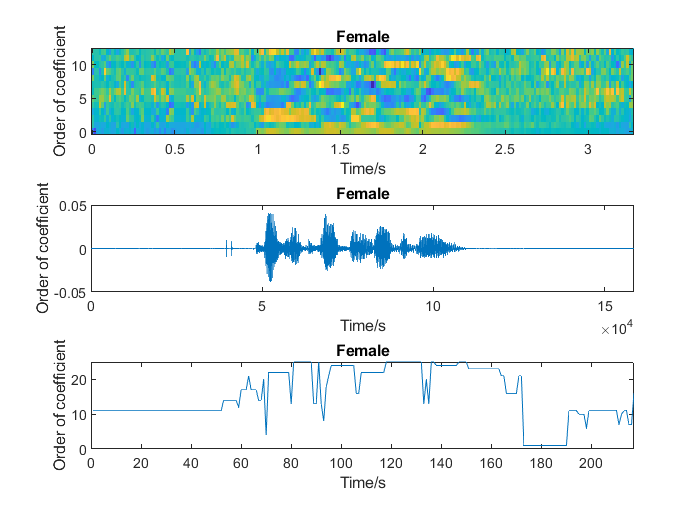

subplot(3,1,1);
imagesc(t0,0:12,test(1:13,:));
% h = colorbar;
% ylabel(h, 'Amplitude');
axis xy;
xlabel('Time/s');
ylabel('Order of coefficient');
title('Female');

subplot(3,1,2);
plot(1:length(x0),x0);
xlim([0 length(x0)]);
xlabel('Time/s');
ylabel('Order of coefficient');
title('Female');

subplot(3,1,3);
plot(1:length(S),S);
xlim([0 length(S)]);
xlabel('Time/s');
ylabel('Order of coefficient');
title('Female');